# Problem 1

clear all; close all; 
D = load('icevelocity.txt') %load in ice velocity data 

D =          0   80.0867
    2.0000   79.4700
    4.0000   80.0735
    6.0000   80.5074
    8.0000   79.5507
   10.0000   80.0381
   12.0000   82.3864
   14.0000   80.1030
   16.0000   79.4725
   18.0000   80.4856


z = D(:,1) % depths 

z =      0
     2
     4
     6
     8
    10
    12
    14
    16
    18


v = D(:,2) % velocities 

v =    80.0867
   79.4700
   80.0735
   80.5074
   79.5507
   80.0381
   82.3864
   80.1030
   79.4725
   80.4856


figure(1);

c = [0,1,2,3,4]; %set up degrees for testing 
P = {} %create empty cell array 


P =

  0×0 empty cell array



Y = zeros(length(v),length(c)) %create empty vecotr for speed 

Y =      0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0
     0     0     0     0     0


Rms = zeros(1,5)

Rms =      0     0     0     0     0


S{1} = 'data'

S = 1×1 cell array
    {'data'}


for i = 1:numel(c)
    x = c(i)
    P{i} = polyfit(z,v, x) % call ployfit function for each degree to be tested 
    Y(:,i) = polyval(P{i},z) % finds polyval values from P polyfit inputs
    Rms(i) = sqrt(mean((v-Y(:,i)).^2)) %finds rmse of plyval vaules from actual velocities 
    S{i+1}= (strcat('Degree =', num2str(x), 'RMSE =', num2str(Rms(i))))
end

x = 0

P = 1×1 cell array
    {[75.4946]}


Y =    75.4946         0         0         0         0
   75.4946         0         0         0         0
   75.4946         0         0         0         0
   75.4946         0         0         0         0
   75.4946         0         0         0         0
   75.4946         0         0         0         0
   75.4946         0         0         0         0
   75.4946         0         0         0         0
   75.4946         0         0         0         0
   75.4946         0         0         0         0


Rms =     5.0855         0         0         0         0


S = 1×2 cell array
    {'data'}    {'Degree =0RMSE =5.0855'}


x = 1

P = 1×2 cell array
    {[75.4946]}    {[-0.0821 82.8820]}


Y =    75.4946   82.8820         0         0         0
   75.4946   82.7178         0         0         0
   75.4946   82.5537         0         0         0
   75.4946   82.3895         0         0         0
   75.4946   82.2254         0         0         0
   75.4946   82.0612         0         0         0
   75.4946   81.8970         0         0         0
   75.4946   81.7329         0         0         0
   75.4946   81.5687         0         0         0
   75.4946   81.4045         0         0         0


Rms =     5.0855    2.6957         0         0         0


S = 1×3 cell array
    {'data'}    {'Degree =0RMSE =5.0855'}    {'Degree =1RMSE =2.6957'}


x = 2

P = 1×3 cell array
    {[75.4946]}    {[-0.0821 82.8820]}    {[-7.7899e-04 0.0581 78.7222]}


Y =    75.4946   82.8820   78.7222         0         0
   75.4946   82.7178   78.8354         0         0
   75.4946   82.5537   78.9423         0         0
   75.4946   82.3895   79.0430         0         0
   75.4946   82.2254   79.1374         0         0
   75.4946   82.0612   79.2257         0         0
   75.4946   81.8970   79.3077         0         0
   75.4946   81.7329   79.3834         0         0
   75.4946   81.5687   79.4530         0         0
   75.4946   81.4045   79.5163         0         0


Rms =     5.0855    2.6957    1.8895         0         0


S = 1×4 cell array
    {'data'}    {'Degree =0RMSE =5.0855'}    {'Degree =1RMSE =2.6957'}    {'Degree =2RMSE =1.8895'}


x = 3

P = 1×4 cell array
    {[75.4946]}    {[-0.0821 82.8820]}    {[-7.7899e-04 0.0581 78.7222]}    {[-6.6305e-06 0.0010 -0.0700 80.5917]}


Y =    75.4946   82.8820   78.7222   80.5917         0
   75.4946   82.7178   78.8354   80.4556         0
   75.4946   82.5537   78.9423   80.3272         0
   75.4946   82.3895   79.0430   80.2064         0
   75.4946   82.2254   79.1374   80.0926         0
   75.4946   82.0612   79.2257   79.9857         0
   75.4946   81.8970   79.3077   79.8852         0
   75.4946   81.7329   79.3834   79.7910         0
   75.4946   81.5687   79.4530   79.7026         0
   75.4946   81.4045   79.5163   79.6198         0


Rms =     5.0855    2.6957    1.8895    1.7322         0


S = 1×5 cell array
    {'data'}    {'Degree =0RMSE =5.0855'}    {'Degree =1RMSE =2.6957'}    {'Degree =2RMSE =1.8895'}    {'Degree =3RMSE =1.7322'}


x = 4

P = 1×5 cell array
    {[75.4946]}    {[-0.0821 82.8820]}    {[-7.7899e-04 0.0581 78.7222]}    {[-6.6305e-06 0.0010 -0.0700 80.5917]}    {[-1.2966e-08 -1.9626e-06 4.7306e-04 -0.0488 80.4099]}


Y =    75.4946   82.8820   78.7222   80.5917   80.4099
   75.4946   82.7178   78.8354   80.4556   80.3142
   75.4946   82.5537   78.9423   80.3272   80.2222
   75.4946   82.3895   79.0430   80.2064   80.1337
   75.4946   82.2254   79.1374   80.0926   80.0488
   75.4946   82.0612   79.2257   79.9857   79.9672
   75.4946   81.8970   79.3077   79.8852   79.8888
   75.4946   81.7329   79.3834   79.7910   79.8136
   75.4946   81.5687   79.4530   79.7026   79.7414
   75.4946   81.4045   79.5163   79.6198   79.6720


Rms =     5.0855    2.6957    1.8895    1.7322    1.7309


S = 1×6 cell array
    {'data'}    {'Degree =0RMSE =5.0855'}    {'Degree =1RMSE =2.6957'}    {'Degree =2RMSE =1.8895'}    {'Degree =3RMSE =1.7322'}    {'Degree =4RMSE =1.7309'}


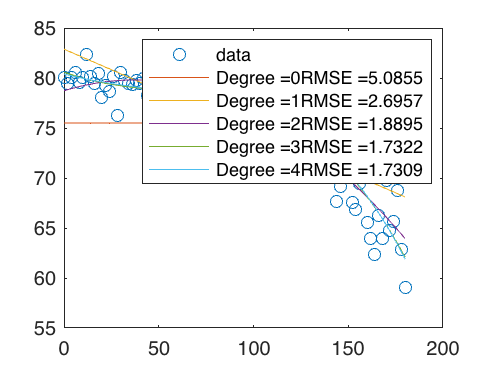



plot(z,v, 'o', z, Y, '-') %plots the velocities versus depth 
legend(S)



% plot(z,v, 'o', z, Y, '-')
% legend(strcat('RMSE is', num2str(Rms(2))))
% plot(z,v, 'o', z, Y{1,3}, '-')
% legend(strcat('RMSE is', num2str(Rms(3))))
% plot(z,v, 'o', z, Y{1,4}, '-')
% legend(strcat('RMSE is', num2str(Rms{4})))
% plot(z,v, 'o', z, Y{1,5}, '-')
% legend(strcat('RMSE is', num2str(Rms{5})))


## Problem 2

clear  P S Y Rms

P = {};

Rms = zeros(1,5);
S{1} = 'data'

S = 1×1 cell array
    {'data'}


perc = 0.9 % 90 percent of data

perc = 0.9000

Ix = 1:length(v);
id = round(length(v)*perc);  %length of samples 
Y = zeros(id,length(c));
 
for i = 1:numel(c)
    for q = 1:1000
        R = randsample(Ix, id); %randomly smaple Ix, and id arrays 
        vt = v(R); %test velocities 
        zt = z(R);% test depths
        x = c(i);% give degree for model 
        P{i}(q,:) = polyfit(zt,vt, x) ;% stores all the columns for qth row in the P cell array 
        Y(:,i) = polyval(P{i}(q,:),zt); %clauclate polyval using polyfit inputs 
        Rms(q,i) = sqrt(mean((vt-Y(:,i)).^2)); %caluculates Rmse of test velocities minus modeled velocites 
        S{i+1}= (strcat('Degree =', num2str(x), 'RMSE =', num2str(Rms(i)))); %create stign fo ruseful display 
    end 
end

Rms_mu = mean(Rms) %find mean of Rms

Rms_mu =     5.0732    2.6937    1.8825    1.7283    1.7250


Rms_std = std(Rms) %find standard deviation of Rms

Rms_std =     0.1586    0.0766    0.0552    0.0575    0.0582


% T = [Rms_mu; Rms_std]; 

T = table([c;Rms_mu; Rms_std,], 'VariableNames', {'Data'}, 'RowNames', {'Degree', 'mean RMS', 'Std RMS'})

T = 3×1 table
                                         Data                          
                _______________________________________________________

    Degree            0           1           2           3           4
    mean RMS     5.0732      2.6937      1.8825      1.7283       1.725
    Std RMS     0.15857    0.076553    0.055216    0.057487    0.058169


## Problem 3

clear q P Y S;
nmc= 1000

nmc = 1000

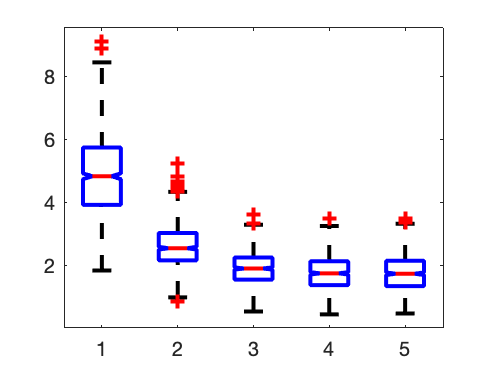

pTrain = 0.9; 
%still use perc from last question for 90%
rmseCV = zeros(nmc, length(c)); %create empty cell array 
for q = 1:length(c)
    for p = 1:nmc
    [trainset, testset] = getTrainTest([z,v], pTrain);
    ztrain = trainset(:,1); % depths for training 
    vtrain = trainset(:,2); % velocitites for training 
    ztest = testset(:,1); % depths for testing
    vtest = testset(:,2); % velocities for testing 
    P = polyfit(ztrain, vtrain, c(q)); %use polyfit function on test sets 
    Y = polyval(P, ztest) ; %evaluate at the test depths 
    rmseCV(p,q) = sqrt(mean((vtest-Y).^2)); 
    end 
end 

figure(2); 
h = boxplot(rmseCV, 'notch', 'on', 'labels', {'1','2','3','4','5'});
set(h, 'linewidth', 2); 

## Problem 4

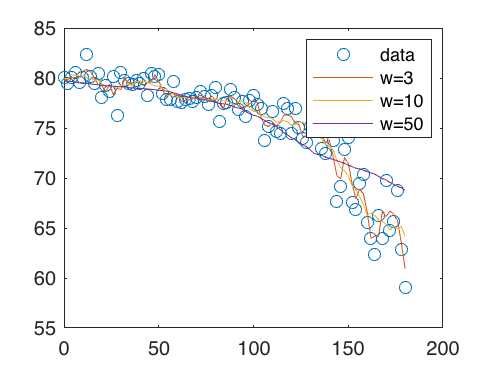

clear q p Ix figure(4); 
figure(4); clf  
plot(z,v, 'o') %plot

winsize =[3 10 50];
z0 = 0:2:180; %sample size
for q = 1:length(winsize)
    for p = 1:length(z0)
        Ix = find(z>(z0(p)-winsize(q)) & z<(z0(p)+winsize(q))); %find values within window
        um(p,q) = mean(v(Ix)); %take mean of values within window Ix
      
    end
end
figure(4); hold on 
plot(z0,um) % plots z0 values against mean values within window size 
legend('data', 'w=3', 'w=10','w=50')

## Problem 5

%weighted moving window 
um2= {} %creat empty cell array 


um2 =

  0×0 empty cell array



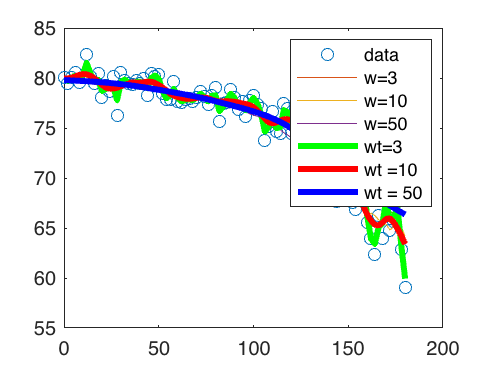

for r = 1:length(winsize)
   um2{r} = nonparametric_smooth(z,v,z0, winsize(r)); %call nonparametric_smooth function and test on all defined windows sizes 
end
hold on 
plot(z0, um2{1}, 'g', 'linewidth', 3) %these all plot the lines with different degrees 
plot(z0, um2{2}, 'r', 'linewidth', 3)
plot(z0, um2{3}, 'b', 'linewidth', 3)
legend('data', 'w=3', 'w=10','w=50', 'wt=3', 'wt =10', 'wt = 50')

## Problem 6

% find optimal window 
clear q rmseCV ztest vtest ztrain vtrain p ;
nmc= 1000  % values to sample

nmc = 1000

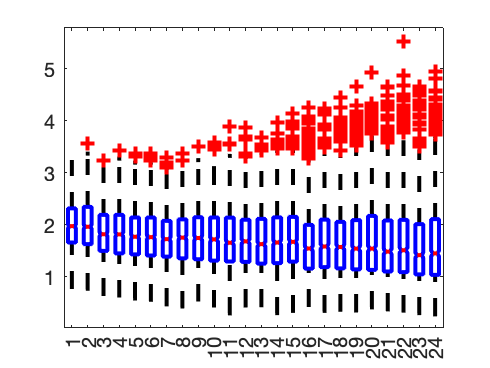

pTrain = 0.9; % test 90% of data 
P_u = {}; %create empty cell array 
Y_u ={}; %create emtpy cell array 
%still use perc from question 2 for 90%
winsize= 3:2:50;
rmseCV = zeros(nmc, length(winsize));
for q = 1:length(winsize)
    for p = 1:nmc
    [trainset, testset] = getTrainTest([z,v], pTrain); %call functin getTrainTest
    ztrain = trainset(:,1); % depths for training 
    vtrain = trainset(:,2); % velocitites for training 
    ztest = testset(:,1); % depths for testing
    vtest = testset(:,2); % velocities for testing 
    P_u{q}(p,:) = nonparametric_smooth(ztrain,vtrain,z0, winsize(q)); %use nonparamtric_smooth curve on test sets 
    Y_u{q}(p,:) = nonparametric_smooth(ztest,vtest,z0, winsize(q)) ; %evaluate at the test depths 
    rmseCV(p,q) = sqrt(nanmean((Y_u{q}(p,:)-P_u{q}(p,:)).^2));  % calculate rmse values for Y and P cell arrays 
    end 
end 
%'labels', {'3','10','50'}
figure(5); 
H = boxplot(rmseCV, 'notch', 'on'); %create boxplot 
set(H, 'linewidth', 2); 

## Answer: The optimal Window size is 47

## Problem 7

clear um; 
g =9.8 % [m/s^2]

g = 9.8000

rho = 917 %[kg/m^3]

rho = 917

theta = 10*pi/180 %convert theta to radian 

theta = 0.1745

n = 2:0.01:4; %create range of n values to find optimum n value for function 
A = 1e-18:0.1e-18:10e-18; % define range of A values to test 
rms = zeros(length(A),length(n)); % create empty data array for rmse values 
for p =1:length(n) %loop through values of n 
    for q=1:length(A) %loop through values of A 
        um = v(1)-A(q).*(rho*g*sin(theta)).^n(p).*z.^(n(p)+1); %eq  6 in hw 3
        rms(q,p) = sqrt(mean((um-v).^2)); %RMSE for each combo of n and A
    end 
end 


## Problem 8

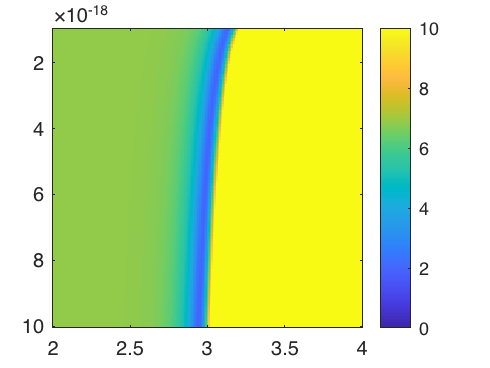


figure(6); clf 
imagesc(n,A,rms, [0 10]); colorbar  %create color bar

## Answer for 7

% using imagesc and the color bar the optimum values for A are any values when
% n = 3 

## Problem 9

fh =@(A)icevel(z,v,A) % function handle, A can be tuned to data in v,and z

fh = function_handle with value:
    @(A)icevel(z,v,A)


A0 = 1e-18

A0 = 1.0000e-18

[Abest, nval]= fminsearch(fh, A0) %create fminsearch handle to fine tune A values from fucntion 

Abest = 4.8375e-18

nval = 1.9649

## Problem 10

clear  P S Y Rms ICE

P = {}; %create empty cell array 
% ICE = {}; 
% Rms = zeros(1,5);
% S{1} = 'data'
perc = 0.9 % 90 percent of data

perc = 0.9000

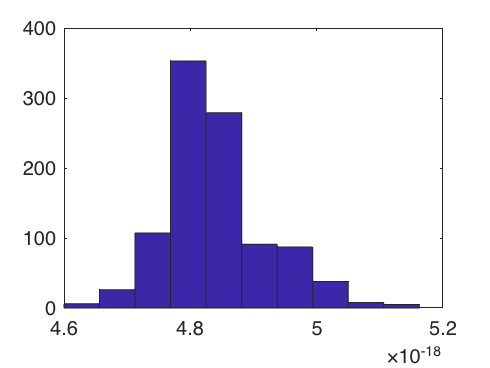

Ix = 1:length(v); % create index  array to keep track of positions 
id = round(length(v)*perc);  %length of samples 
% Y = zeros(id,length(c));
A0 = 1e-18 ; %define intial A value 
% for i = 1:numel()
for q = 1:1000 %for loop for monte carlo evaluations 
        R = randsample(Ix, id); 
        vt = v(R); %test velocities 
        zt = z(R); %test depths 
%         ICE(q) = icevel(zt,vt,A); 
        P =@(A)icevel(zt,vt,A); % function handle, A can be tuned to data in v,and z
        [Abest(q), nval(q)]= fminsearch(P, A0); % Nval is the value of the function that I'm minimizing 
%         P{i}(q,:) = fminsearch(zt,vt, x) ;% stores all the columns for qth row in the P cell array 
%         Y(:,i) = fminsearch(P{i}(q,:),zt);

%         S{i+1}= (strcat('Degree =', num2str(x), 'RMSE =', num2str(Rms(i))));
    end 

figure(7); clf 
hist(Abest); %hist of abest

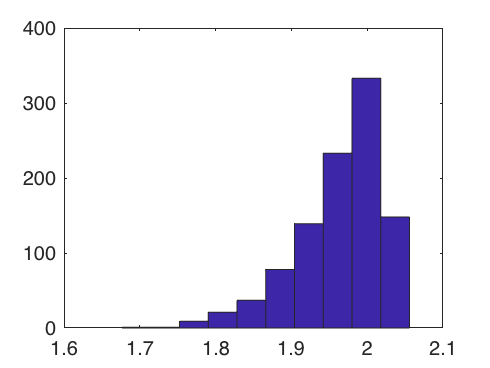

figure(8);clf
hist(nval); %histogram of rmse values 

% xlim([-0.15, 0.15])

## Problem 11

muAbest= mean(Abest); %find mean of Abest array 
sigAbest = std(Abest); %fidn standard deviation of Abest array 
n0=3 %initialize n value

n0 = 3

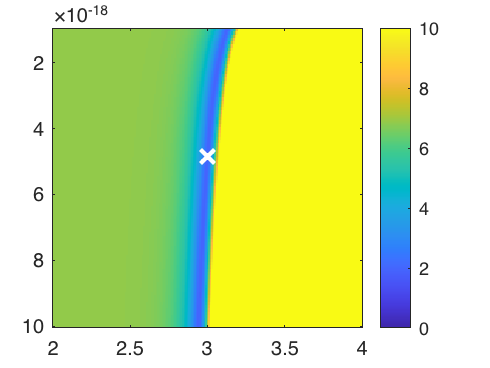


figure(9); %reacreate figure from probelm 8
imagesc(n,A,rms, [0 10]); colorbar; hold on 
plot(n0, muAbest, 'wx', 'Markersize', 10, 'linewidth', 2); hold on  %plot the mean optimum values
errorbar(n0, muAbest, sigAbest, 'w-') %create errorbar 

## Problem 12

rmse_mu = mean(nval); %find the mean of rmse_mu array 
Asim= randn(1000,1).*sigAbest+muAbest; %find simulated model estimation for A values from icevel 
Rsim = randn(1000,1).*std(nval)+rmse_mu; %find the RMSE suimulated values from icevel 


## Problem 13

[H, P] = kstest2(Asim, Abest); %find probablity of asim and Abest being same 
[H1,P1] = kstest2(Rsim, nval); %find the probailty of RMSE values being the same 

## Fmin search function

function rmse = icevel(x,y,A) %define rmse function 
%Inputs: x = independent variable 
%        y = dependent variable 
%         A = parameter in the physics based model 
g =9.8; % [m/s^2]
rho = 917; %[kg/m^3]
theta = 10*pi/180; %convert theta to radian 
% n = 2:0.01:4; 
n = 3; %preallocate the n value for the icevelocity model 
% A = 1e-18:0.1e-18:21e-18; 
ymod = 80.086027-A.*(rho*g*sin(theta)).^n.*x.^(n+1); %define model equation
rmse = sqrt(mean((y-ymod).^2)); %calculate rmse 
end

## Wieghted Moving Window Function 

function ymod = nonparametric_smooth(x,y, xmod, winsize) %define the function 
%this function smooths a 20d dataset using a bisquare kernal 
%input: x = indep vairable [n,1]
%       y = dependent variable  [n,1]
%       xmod = locations of estimates [*,1]
%       winsize = size of window (same uits as x) 
% Output: ymod = nonparametric smoothed estimate 
x = x(:); y=y(:);  %define x and y vectors 
xmod = xmod(:); %give xmod data 
ymod = zeros(size(xmod)); % create emtpy ymod vector for speed 
for i = 1:length(xmod) %loop through all positions in xmod 
    dist = sqrt((x-xmod(i)).^2); %distance from each data point to the estimate location 
    Ix = find(dist<winsize); %find values within window size and save index 
    Ix = Ix(isfinite(y(Ix))); %removing NaNs from Ix 
    if isempty(Ix) %removes empty values 
        ymod(i)=NaN; %use NaN if no data in windown
    else 

        w = 15/16*(1-(dist(Ix)/winsize).^2).^2; %bisquare kernal
        ymod(i) = sum(w.*y(Ix))./sum(w); %unbiased estimate
    end 
end 
end  


## RMSE Function

function rmse=poly1(x,y,A)
%INPUTS:    x = independent variable
%           y = dependent variable
%           A = parameters [slope,intercept]
ymod=A(1)*x+A(2); %define ymod equation 
rmse=sqrt(mean((y-ymod).^2)); %calculate rmse value 
end

## TRAIN TEST FUNCTION

function [trainset, testset] =  getTrainTest(data, pTrain)
%input = data = [ns, nd] ns = number of samples nd = number of dimension
% outputs = trainset = data to use to train model ..
% testset = data for testin model 
[ns,nd] = size(data); %create data array 
nsTrain = round(pTrain *ns); %number of samples to train

Ix = 1:ns; %vector of indices 
IxTrain = randsample(Ix, nsTrain); % randomly grab data 
Ix3 = ones(size(Ix)); %vector of ones
Ix3(IxTrain) = 0 ;%set rows from training data to zero
IxTest = find(Ix3); %indices to the test observations 

trainset = data(IxTrain,:); %datat for training 
testset = data(IxTest,:); %data for testing
end